# **Chapter 18 Mini Quiz**

# Q1

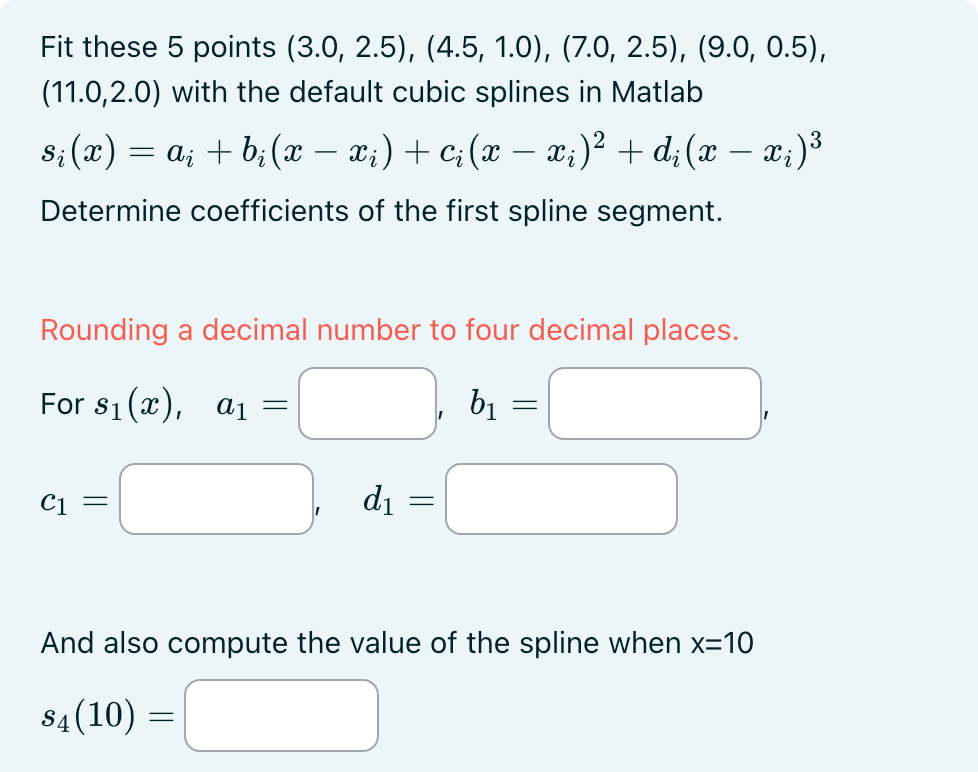

x = [3.0 4.5 7.0 9.0 11.0]

x =     3.0000    4.5000    7.0000    9.0000   11.0000


y = [2.5 1.0 2.5 0.5 2.0]

y =     2.5000    1.0000    2.5000    0.5000    2.0000


figure
plot(x, y, 'o')
axis([0 13 0 3])
hold on

cubic_spline = spline(x, y) % is type of piecewise polynomial

cubic_spline = フィールドをもつ struct :
      form: 'pp'
    breaks: [3 4.5000 7 9 11]
     coefs: [4×4 double]
    pieces: 4
     order: 4
       dim: 1


% get the coefs with `cubic_spline.coefs` in the command window
% ***since in MATLAB, piecewise polynomials are arranged from the LARGEST
% degree to SMALLEST degree, but the coefficients are arranged in the
% OPPOSITE order***
% therefore, answer the first row, from RIGHT TO LEFT

xx = 3.0 : 0.1 : 11.0

xx =     3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000    6.0000    6.1000    6.2000    6.3000    6.4000    6.5000    6.6000    6.7000    6.8000    6.9000    7.0000    7.1000    7.2000    7.3000    7.4000    7.5000    7.6000    7.7000    7.8000    7.9000


yy = ppval(cubic_spline, xx) % ppval - Evaluate piecewise polynomial

yy =     2.5000    2.2438    2.0147    1.8116    1.6334    1.4789    1.3471    1.2369    1.1472    1.0769    1.0248    0.9899    0.9710    0.9672    0.9772    1.0000    1.0345    1.0795    1.1340    1.1968    1.2670    1.3433    1.4246    1.5099    1.5981    1.6881    1.7787    1.8688    1.9575    2.0434    2.1257    2.2031    2.2745    2.3389    2.3952    2.4422    2.4788    2.5041    2.5167    2.5157    2.5000    2.4688    2.4230    2.3638    2.2924    2.2101    2.1180    2.0176    1.9098    1.7961


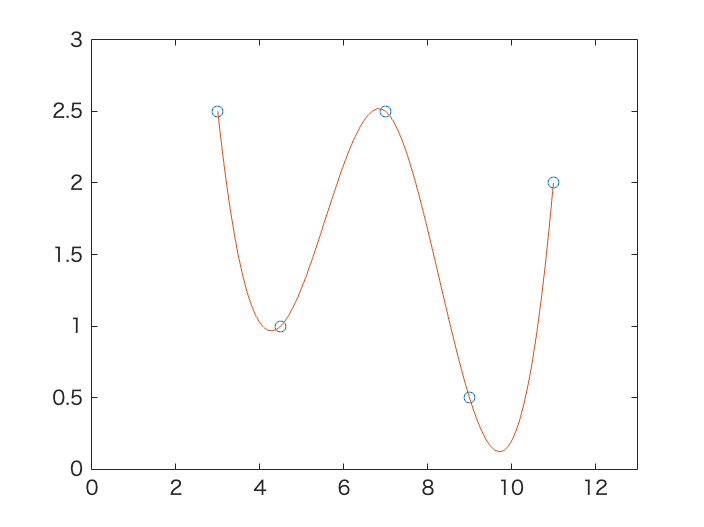


plot(xx, yy, '-')
hold off


xtest = 10

xtest = 10

ypred = spline(x, y, xtest)

ypred = 0.1974

# Q2

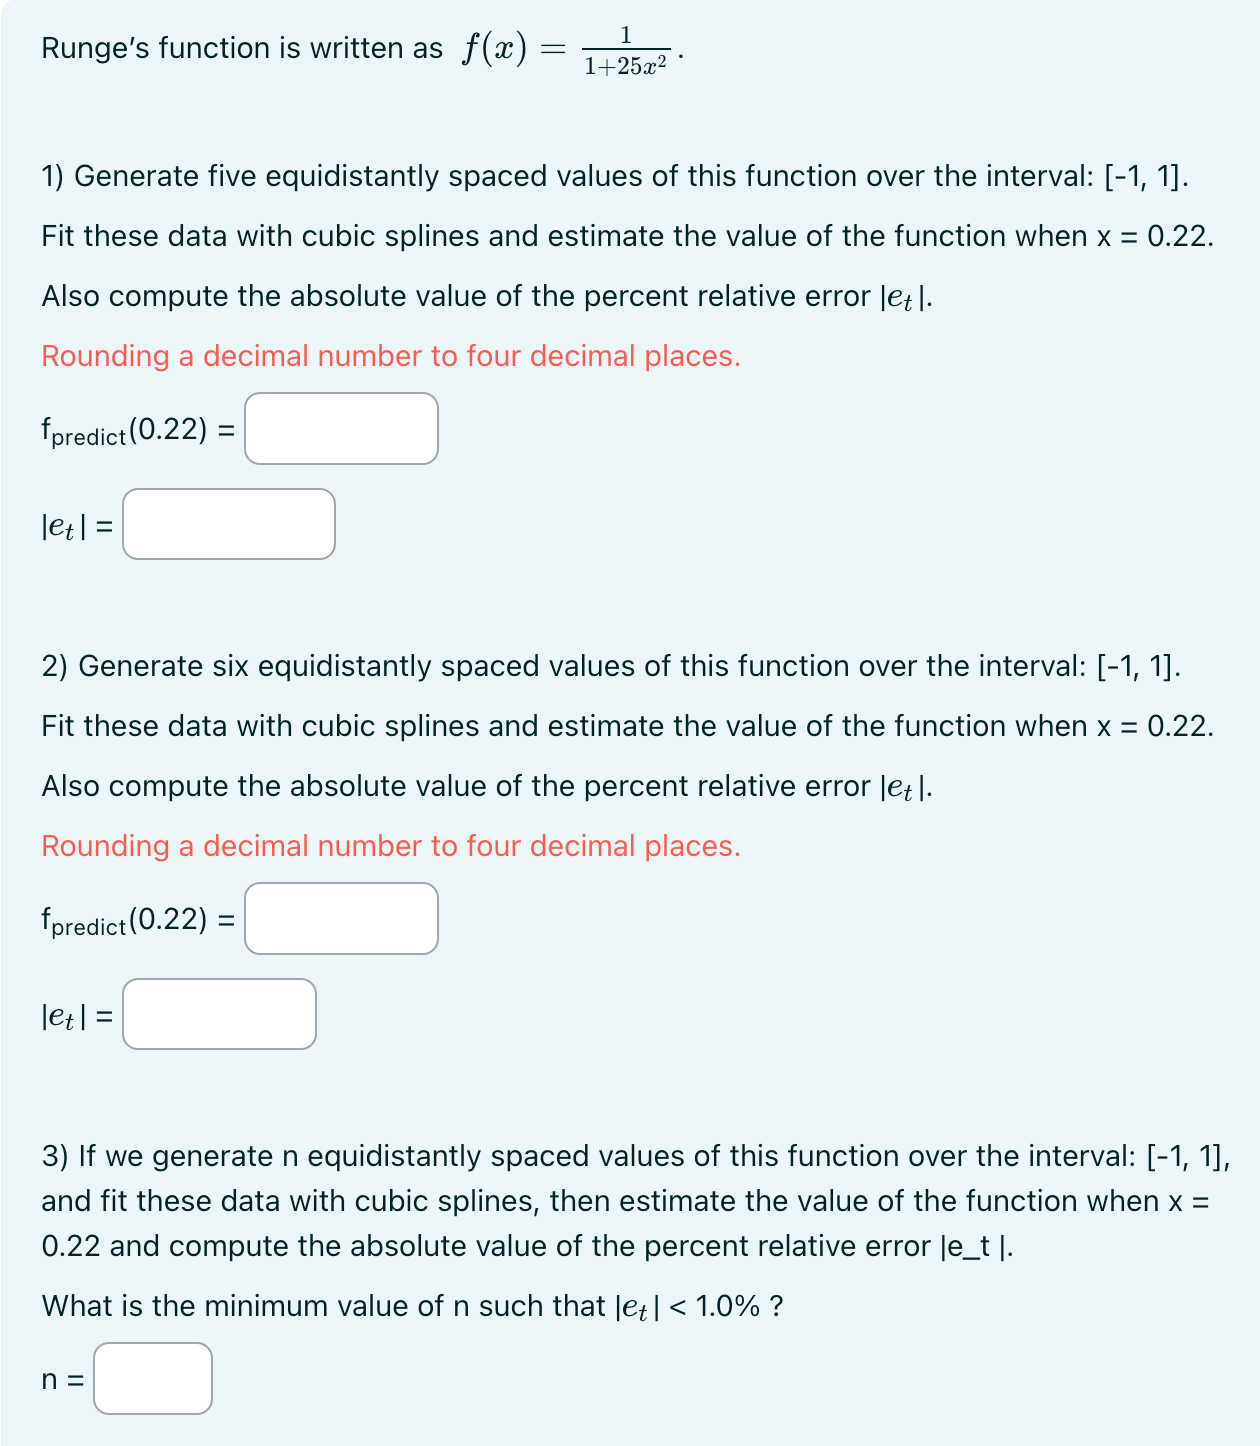

Runge's function

xx = linspace(-1, 1)

xx =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


yy = 1 ./ (1 + 25*xx.^2)

yy =     0.0385    0.0400    0.0416    0.0434    0.0452    0.0472    0.0492    0.0515    0.0538    0.0564    0.0591    0.0620    0.0652    0.0685    0.0722    0.0761    0.0803    0.0849    0.0899    0.0953    0.1012    0.1077    0.1147    0.1225    0.1310    0.1404    0.1507    0.1622    0.1749    0.1891    0.2049    0.2226    0.2424    0.2647    0.2897    0.3179    0.3497    0.3855    0.4256    0.4706    0.5206    0.5756    0.6354    0.6988    0.7642    0.8288    0.8889    0.9401    0.9776    0.9975


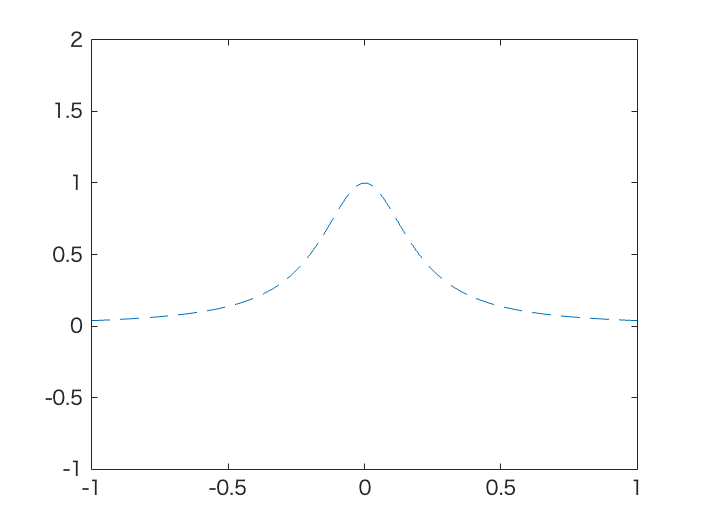

figure
plot(xx, yy, '--')
hold on
axis([-1 1 -1 2])

Fit 5 points with not-a-knot cubic spline

% generate the points
x = linspace(-1, 1, 5);
y = 1 ./ (1 + 25*x.^2);
% fit those points
yy_cubic_spline = spline(x, y, xx);

xtest = 0.22

xtest = 0.2200

ytrue = 1 ./ (1 + 25*xtest.^2);
ypred = spline(x, y, xtest)

ypred = 0.7657

abs_et = abs((ytrue - ypred)/ytrue) * 100

abs_et = 69.2203

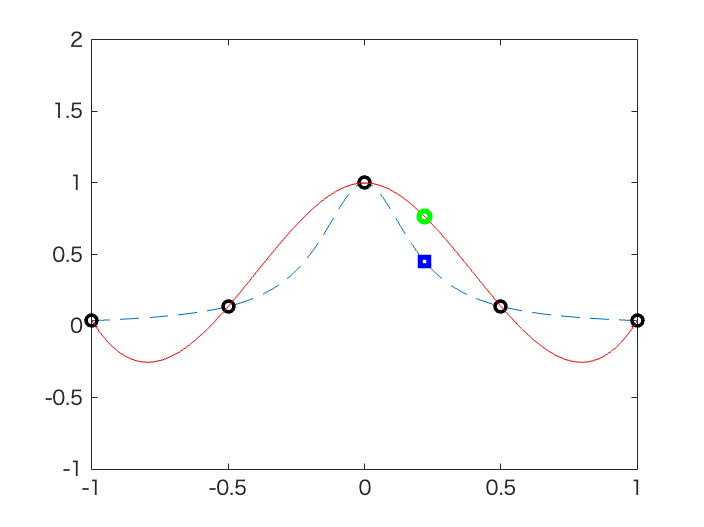


figure
plot(xx, yy, '--')
hold on
plot(x, y, 'ko', 'LineWidth', 2)
hold on
plot(xx, yy_cubic_spline, 'r-')
hold on
plot(xtest, ytrue, 'bs', 'LineWidth', 4)
hold on
plot(xtest, ypred, 'go', 'LineWidth', 3)
axis([-1 1 -1 2])

Fit 6 points with not-a-knot cubic spline

% generate the points
x = linspace(-1, 1, 6);
y = 1 ./ (1 + 25*x.^2);
% fit those points
yy_cubic_spline = spline(x, y, xx);

xtest = 0.22

xtest = 0.2200

ytrue = 1 ./ (1 + 25*xtest.^2);
ypred = spline(x, y, xtest)

ypred = 0.4856

abs_et = abs((ytrue - ypred)/ytrue) * 100

abs_et = 7.3268

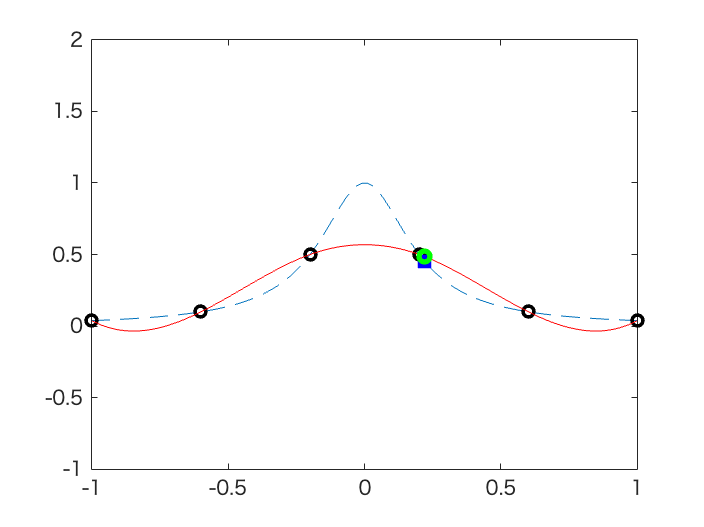


figure
plot(xx, yy, '--')
hold on
plot(x, y, 'ko', 'LineWidth', 2)
hold on
plot(xx, yy_cubic_spline, 'r-')
hold on
plot(xtest, ytrue, 'bs', 'LineWidth', 4)
hold on
plot(xtest, ypred, 'go', 'LineWidth', 3)
axis([-1 1 -1 2])

Fit *n* points with not-a-knot cubic spline until |et| < 1.0%

% generate the points
x = linspace(-1, 1, 13);
y = 1 ./ (1 + 25*x.^2);
% fit those points
yy_cubic_spline = spline(x, y, xx);

xtest = 0.22

xtest = 0.2200

ytrue = 1 ./ (1 + 25*xtest.^2);
ypred = spline(x, y, xtest)

ypred = 0.4506

abs_et = abs((ytrue - ypred)/ytrue) * 100

abs_et = 0.4240

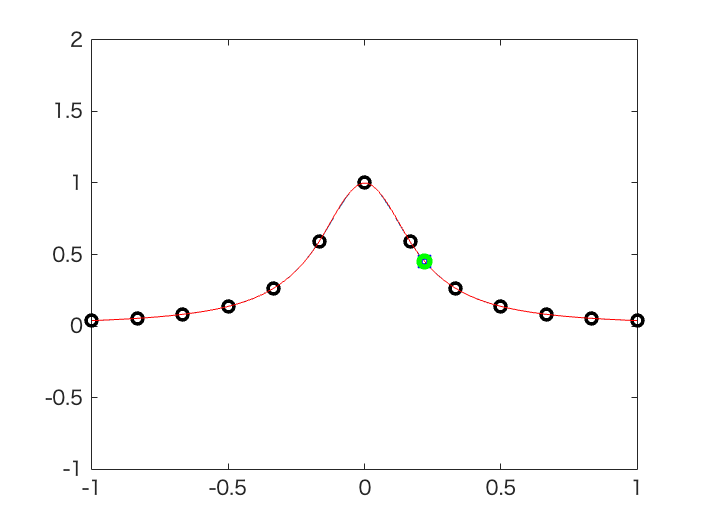


figure
plot(xx, yy, '--')
hold on
plot(x, y, 'ko', 'LineWidth', 2)
hold on
plot(xx, yy_cubic_spline, 'r-')
hold on
plot(xtest, ytrue, 'bs', 'LineWidth', 4)
hold on
plot(xtest, ypred, 'go', 'LineWidth', 3)
axis([-1 1 -1 2])